Santeri Saariokari 253345

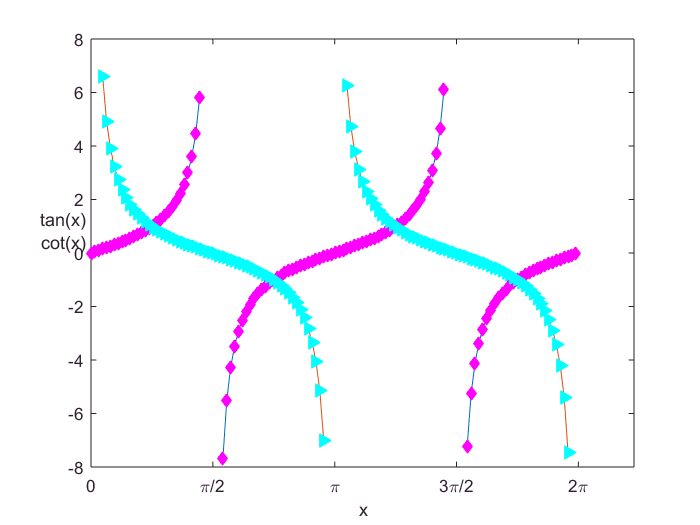

hold on;
x = 0:.05:2*pi;

tan_plot = plot(x,tan(x));
cot_plot = plot(x,cot(x));

cot_plot.YData(abs(cot_plot.YData) > 8) = NaN;
tan_plot.YData(abs(tan_plot.YData) > 8) = NaN;

axis_handle = gca;
set(axis_handle,'XTick',[0 pi/2 pi 3*pi/2 2*pi], 'XTickLabel', {'0' '\pi/2' '\pi' '3\pi/2' '2\pi'});

xlabel('x');
ylabel({'tan(x)' 'cot(x)'}, 'rotation', 0);

set(tan_plot, 'Marker', 'Diamond', 'MarkerSize', 6, 'MarkerEdgeColor', 'm', 'MarkerFaceColor', 'm');
set(cot_plot, 'Marker', '>', 'MarkerSize', 7, 'MarkerEdgeColor', 'c', 'MarkerFaceColor', 'c');